# **Lab 1:  Random variables and estimation theory**

**Statistical Signal Processing (5CTA0) - Lab Assignment**

Lecturers: Simona Turco (Flux 7.076), Franz Lampel (Flux 7.064)

Assistants: Yizhou Huang (Flux 7.078), Ben Luijten (Flux 7.078)

**Group 13**

**Students:**

**Chris Osse - 1234075**

**Max van Ijsseldijk - 1325930**

**Paula Passet - 1367889**

**Stijn Leenen - 1001901**

## General info and guidelines

To complete and submit the Labs:

`•`All students must register on Canvas.

`•`Each lab will be carried out in groups of 4 students, which must register on Canvas.

`•`All information and data will be available on Canvas.

`•`Each group must carry out all assignments of the Lab and hand in a report for each Lab.

`•`**The report is obtained by exporting this matlab live script as pdf. This is the only file that you need to provide.**

`•`**Sometimes, ruuning the code within livescript might be slow. You may consider to first implment and test your code in a seperate .m file, and copy the code to livescript in the end. **

`•`The report must be submitted through Canvas.

`•`In case of problems, the labs can alternatively be submitted by printing them and putting them in the post box of one of the teaching assistants (Flux floor 7th, opposite to the secretary), together with an email notification.

`•`The report must be accompanied by the peer-review form, which is used to provide an indication of the contribution of each student in the group. The link to the peer review form is available on Canvas.

`•`If plagiarism is detected, the Lab will be judged with 0 points.

Below, some useful tips for working with MATLAB and for producing a neat Lab report:

`•`Make use of comments to divide the code in sections and facilitate its understanding.

`•`Use the command `doc or` `help` to learn how to use a specific MATLAB functions (e.g.`doc stem`).

`•`Make sure that all your graphs are easily readable, even when printed in black and white. Use for this purpose the options of the plot/stem function to properly increase the dimension and/or change the marker symbols, for example:

`•`Make sure that all your graphs have their axes properly labeled and a legend when several signals are plotted on the same graph. Also, make sure the all the text is readable. Below some useful commandsfor these purposes:

## Credits and deadlines

Each Lab counts for 15% of the final grade, for a total of 30%. The remaining 70% is determined by the final written exam. 

Please submit this lab on Canvas by 10/10/21 at 23:59.

## Introduction

In this lab, we are going to prove the frequentist definition of probability and investigate sampling of random variables and the central-limit theorem in MATLAB. We are also going to implement maximum-likelood and least-square estimators, including iterative maximization approaches, and learn how to evaluate the estimator performance by calculating the Cramer-Rao Lower Bound to determine the minimum variance. 

## **Assignment 1 - Probablity and frequency**

The *classic* defintion of probability states that if a random experiment can result in $N$ mutually exclusive and equally likely outcomes, and if event $A$results from the occurence of $N_A$of these outcomes, then the probability of $A$ is defined as


$$Pr[A] =  \frac{N_A}{N}. ~~~~~~~(1)$$
 

The *frequentist* definition of probability, also known as *relative probability*, calculates probability based on how often an event occurs. The relative frequency of an event is given by


$$f_A =\frac{\textrm{number}\;\textrm{of}\;\textrm{occurrences}\;\textrm{of}\;\textrm{event}\;A}{\textrm{total}\;\textrm{number}\;\textrm{of}\;\textrm{observations}}=\frac{N\left(A\right)}{A}\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$


where $N\left(\cdot \right)$ denotes the number of occurrences of a certain event and $N$ the total number of observations. The relative frequency can be understood as how often event $A$ occurs relative to all observations. 

**HINT**: Read [here](https://signalprocessingsystems.netlify.app/courses/5cta0/mathematicalbackground_probability_definitions/#definition-of-probability) before you start

**QUESTION 1a**

Suppose we roll 2 dice and we define event $A$={two times the same number} and ${B=\;A}^C$= {two different numbers}. What are the probabilities $\Pr \left(A\right)$and $\Pr \left(B\right)$? Write down your problem-solving process. 

**ANSWER**: (write here your workout)

A dice has 6 sides/numbers which are all equaly likely to be thrown. This means that the probability that a specific number in the range 1 till 6 is:

Pr(a number between 1 and 6) = 1/6

Event A thus has a probabilty of:

Pr(A) = 1/6 * 1/6 * 6 = 1/32 * 6 = 1/6

The *6 comes from the fact that is can be any of the 6 numbers.

The probability of event B happening is:

Pr(B) = 1/6 * 5/6  * 6 = 5/6

Event A and B cover the entire sample space, since 

Pr(A) + Pr(B) = 1/6 + 5/6 = 1

**QUESTION 1b**

Implement a simulation of the above experiment in MATLAB and repeat the experiment for a number of trials $N$ equal to 50, 500, and 1000. For each number of trial, create a bar plot with the relative frequencies of $f_A$ and $f_B$ of each event. You can do this in a subplot with three plots, one plot for each $N\ldotp$ Finally, plot the relative frequencies $f_A$ and $f_B$ as a function of the number of trials $N$, with $N$ranging from 1 to 2000. You can plot $f_A$ and $f_B$ on the same plot or on two separate plots.

A useful command to simulate this experiment is `random`

Note: (optional) to avoid having a different result everytime you run the algorithm, you may fix the random seed using the function `rng. `

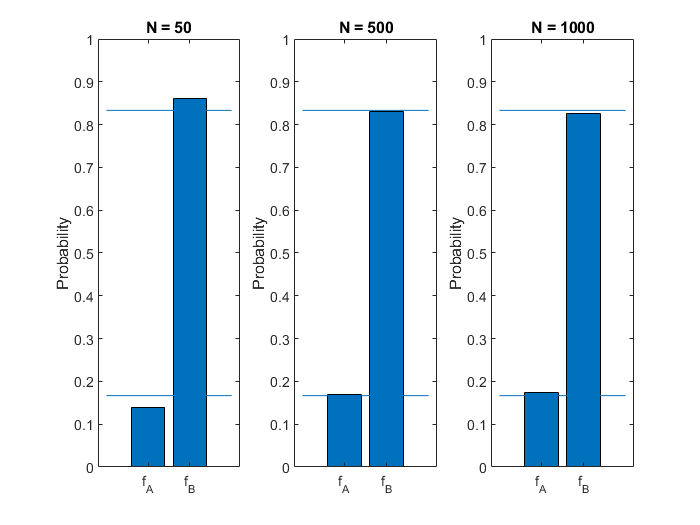

% ---------------------------------------------
% Generate a subplot with three bar plots to show the relative frequencies 
% of events A and B, with N = 100, 500 and 1000 respectively.
% ---------------------------------------------
% your code goes here (~10-15 lines of code)
%

rng(69420)
N = [50, 500, 1000];
f_A = [0 0 0];

figure, 
for i = 1:length(N)                     % Go over all items in N
    n_A = 0; 
    
    for j = 1:N(i)                      % Go over N trials
        diceroll1 = random('Discrete Uniform', 6);    % Random throw 1
        diceroll2 = random('Discrete Uniform', 6);    % Random throw 2

        if diceroll1 == diceroll2       % If event A happens...
            n_A = n_A + 1;              % ... add 1 to number of occurences of A 
        end 
    end
    
    f_A(i) = n_A/N(i);                  % Calculate frequency of event A
    
    subplot(1,3,i)                      % Make plots
    bar([f_A(i), 1-f_A(i)])
    set(gca, 'ylim', [0 1])
    title(['N = ', num2str(N(i))])
    hl1 = line([0 3],[1/6 1/6]);
    hl2 = line([0 3],[5/6 5/6]);
    set(gca, 'XTicklabel', {'f_A', 'f_B'})
    ylabel('Probability')
end

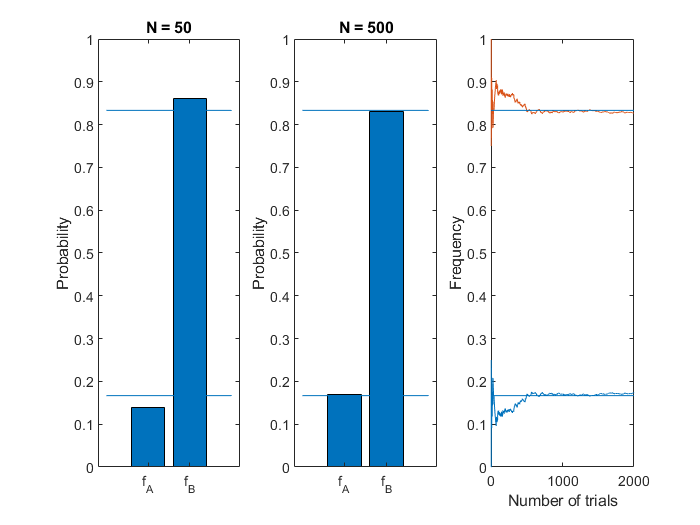

%---------------------------------------------
%% Generate a plot of the relative frequencies fA and fB as a function 
% of the number of trials.
%---------------------------------------------
% your code goes here (~10 lines of code)

rng(69420)
N = 2000; n_A = 0;              % Set Number of trials to 2000

for i = 1:N
    diceroll1 = random('Discrete Uniform', 6);  % Random throw 1
    diceroll2 = random('Discrete Uniform', 6);  % Random throw 2

    if diceroll1 == diceroll2   % If event A happens...
        n_A = n_A + 1;          % ... add 1 to number of occurences of A 
    end
    
    f_A(i) = n_A/i;             % Calculate frequency of event A
end

plot(f_A)                       % Plot frequency of A over N
hold on
plot(1 - f_A)                   % Plot frequency of B over N
hl1 = line([0 N],[1/6 1/6]);
hl2 = line([0 N],[5/6 5/6]);
set(gca, 'ylim', [0 1])
ylabel('Probability')
xlabel('Number of trials')

**QUESTION 1c**

Does your results for N = 50, 500 and 1000 align with what you got in 1a? If not, why?

**ANSWER:**

For N=50, one can clearly see a difference from the 1/6 and 5/6. This is because the number of observations is relatively small. At N=1000, one can see the probabilities are pretty much equal to the analytical solutions. This is just coincidence, since at N=1000, they differ more again. However, this difference is much smaller compared to the difference at N=50, because of a much larger number of observations.

**QUESTION 1d**

What is the minimum number of trials $N_{\textrm{conv}}$ for which $f_A$  converges to the real probability, as defined in (2), with a maximum error of 10%? Convergence means that the absolute error is always below 10%. To calculate this, you can first calculate the error as a function of the number of trials. You can plot this function and then plot one line at 10% and one line -10%. Finally, you can write code to calculate $N_{\textrm{conv}}$.

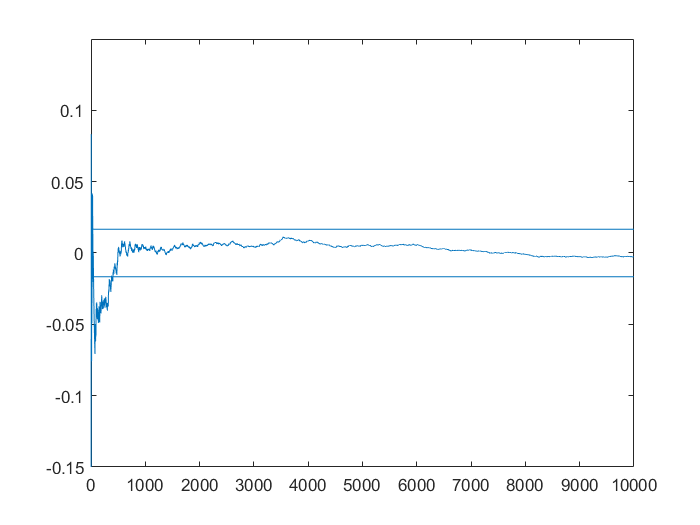

% ---------------------------------------------
% Plot the probability error as a function of 
% the number of trials and calculate the minimum N
% required for the error to converge below 10% (use 'line' to plot two +-10% lines)
%
% ---------------------------------------------
% your code goes here (~10 lines of code)
%

rng(69420)
pr_A = 1/6; n_A = 0; N=10000; Nconv=Inf;    % Set Nconv to infinity

for i = 1:N
    diceroll1 = random('Discrete Uniform', 6);	% Random throw 1
    diceroll2 = random('Discrete Uniform', 6);  % Random throw 2

    if diceroll1 == diceroll2       % If event A happens...     
        n_A = n_A + 1;              % ... add 1 to number of occurences of A 
    end
    
    err_fA(i) = n_A/i - pr_A;       % Calculate error f_A
    
    if abs(err_fA(i)) <= pr_A*0.1 && Nconv == Inf       
            % If error is below 10% and Nconv is still inf...
        Nconv = i;                                      
            % ... set Nconv to current trial
    elseif abs(err_fA(i)) > pr_A*0.1 && Nconv ~= Inf    
            % If error is above 10% and Nconv is not inf...
        Nconv = Inf;                                 	
            % ... set Nconv to Inf again
    end
end

figure;                             % Make plot
plot(err_fA)
hl1 = line([0 N],[pr_A*0.1 pr_A*0.1]);
hl2 = line([0 N],[-pr_A*0.1 -pr_A*0.1]);
set(gca, 'ylim', [-0.15 0.15])


Nconv

Nconv = 404

**ANSWER****:**

$N_{\textrm{conv}}$ is equal to 404 with the seed set to 69420. However, the value changes for different seeds.

## Assignment 2 - Mean and variance of a random variable

In the following experiment, we construct a random variable $X_N \left\lbrack n\right\rbrack \;$as the sum of $N$ RVs $x_i$ as follows:

$X_N =\frac{1}{N}\sum_{i=1}^N x_i$     with $N=1,\;2,\;\ldotp \ldotp \ldotp$                         (3)

The random processes $x_i \left\lbrack n\right\rbrack$, for $i=1,2,\ldotp \ldotp \ldotp ,N$, are $N$IID stationary Gaussian random processes with mean $E\left\lbrace x_i \left\lbrack n\right\rbrack \right\rbrace =\mu_i =\mu$ and variance $E\left\lbrace x_i^2 \left\lbrack n\right\rbrack \right\rbrace =\sigma_i^2 =\sigma^2$.

**HINT:** Read [here](https://signalprocessingsystems.netlify.app/courses/5cta0/mathematicalbackground_probability_variables/#expected-value) before you start.

**QUESTION 2a**

Calculate an analytical expression for the mean $\mu_{X_N } =E\left\lbrace X_N \right\rbrace$and the variance $\sigma_{X_N }^2 =E\left\lbrace X_N^2 \right\rbrace -E{\left\lbrace X_N \right\rbrace }^2$ of the sum RV $X_N$ as a function of $N\ldotp$ HINT: The $x_i$ are IID (independent, identically distributed)

**ANSWER**: Please insert the analytical expression here.


$$\mu_{X_N } =E\left\lbrace X_N \right\rbrace =E\left\lbrace \frac{1}{N}\sum_{i=1}^N x_i \right\rbrace =\frac{1}{N}\sum_{i=1}^N E\left\lbrace x_i \right\rbrace =\frac{1}{N}\sum_{i=1}^N \mu_i =\frac{1}{N}\sum_{i=1}^N \mu =\mu$$



$$\begin{array}{l}
\sigma_{X_N }^2 =E\left\lbrace X_N^2 \right\rbrace -E{\left\lbrace X_N \right\rbrace }^2 =E\left\lbrace {\left(\frac{1}{N}\sum_{i=1}^{N} x_i \right)}^2 \right\rbrace -{\mu_{X_N } }^2 ={\left(\frac{1}{N}\right)}^2 E\left\lbrace {\left(\sum_{i=1}^{N} x_i \right)}^2 \right\rbrace -\text{ }\mu^2 \\
=\frac{1}{N^2 }\sum_{i=1}^{N} \sigma_i^2 -\text{ }\mu^2 =\frac{1}{N^2 }N\sigma^2 -\text{ }\mu^2 =\frac{\sigma^2 }{N}-\text{ }\mu^2 
\end{array}$$


**QUESTION 2b**

Implement a Monte-Carlo simulation in MATLAB to generate RVs $x_i$, for $i=1,2,\ldotp \ldotp \ldotp ,5$, with uniform distribution. For each of these RVs, generate 1000 IID samples with parameters of the uniform distribution $a_{x_i } =a_x =-1$, and $b_{x_i } =b_x =1$. Construct $X_{\textrm{uN}}$ for $N=1,\;2,\;\textrm{and}\;5$ and make a *subplot* of $X_{\textrm{u1}}$, $X_{\textrm{u2}}$ and $X_{\textrm{u5}}$.

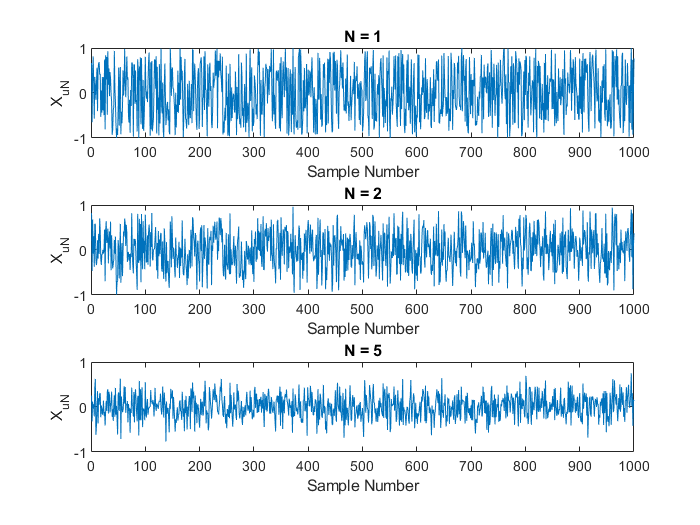

% ---------------------------------------
% Generate 1000 RVs with uniform distribution
% ---------------------------------------
% your code goes here (~5 lines of code)

nSamples = 1000;
N = 5;
a = -1;
b = 1;

%P_uni = ; % Monte-Carlo simulation
for i = 1:N                     % For N rows...
    for j = 1:nSamples          % ... create 1000 samples...
        x(i,j) = unifrnd(a,b); 	% ...uniformly distributed between a and b
    end
end

% ---------------------------------------
% Calculate sum of N processes and make the plot with subplot function.
% Don't forget to add label, title, etc to the figures.
% ---------------------------------------
% your code goes here (~15 lines of code)


for i = [1 2 5]                             % For i = 1, 2 and 5
    for j = 1:nSamples                      % Go over all samples
        Xu(i,j) = sum(x(end-N+1:i,j))/i;    % Sum all it
    end
    
    if i == 5                               % Make plot for i = 5
        subplot(3,1,i-2)  
    else
        subplot(3,1,i)                      % Make plot for i = 1, 2
    end
    plot(Xu(i,:))
    title(['N = ', num2str(i)])
    xlabel('Sample Number')
    ylabel('X_{uN}')
end

**QUESTION 2c**

Do the plots of **QUESTION 2b** follow the analytical results that you found in **QUESTION 2a**? Can you give a general statement about the mean and variance of a RV which consists of the normalized sum of $N$ RVs with same distribution and finite mean and variance?

**ANSWER: **

Yes, they follow the analytical results, since the mean is equal in all plots (0). The mean was indeed independent on the number of RVs. However, the variance was found to be dependent on the number of RVs, which can also be seen in the plots. The variance indeed becomes 5 times smaller at N=5 compared with N=1.

In general it can be said that that the mean of the normalized sum of $N$ RVs is equal to the mean of the single RV. The variance is dependent on N and the variance of the normalized sum of $N$ RVs is equal to the mean of the single RV devided by the number of RVs.

## Assignment 3 - Sampling a binomial random varaible

Consider an exponential random variable with probability density function (PDF) given by

$p_X \left(x\right)=\left\lbrace \begin{array}{ll}
\lambda \cdot e^{-\lambda x}  & \textrm{for}\;x\ge 0\\
0 & \textrm{elsewhere}
\end{array}\right.$                                  (4)

and cumulative distribution function (CDF) given by 

$P_X \left(x\right)=\left\lbrace \begin{array}{ll}
1-e^{-\lambda x}  & \textrm{for}\;x\ge 0\\
0 & \textrm{elsewhere}
\end{array}\right.$                                (5)

**HINT:** Read [here](https://signalprocessingsystems.netlify.app/courses/5cta0/mathematicalbackground_probability_families/#binomialnp-distribution) before you start.

**QUESTION 3a**

Calculate by hand the expected value of $X$, having $p_X \left(x\right)$ as in Eq. (4), using intergral by parts and variable subsitituion $\lambda x=u$..

**ANSWER**: 

The expected value can be found using the following equation


$$E[X] = \int_{-\infty}^\infty x p(x)dx ,$$


Evaluating this for the PDF given in (4) gives


$$E[X] =  \int_{0}^\infty \lambda x e^{-\lambda x} dx = \frac{1}{\lambda} \int_{0}^\infty ue^{-u} du = \frac{1}{\lambda} \Big( -ue^{-u} \Bigr|_{0}^{\infty} - \int_{0}^\infty -e^{-u} du \Big) = \frac{1}{\lambda} \Big( -ue^{-u}  - e^{-u} \Bigr|_{0}^{\infty} \Big) = \frac{1}{\lambda}.$$


**QUESTION 3b**

Implement your own MATLAB function $\textrm{exponentialRV}\left(\textrm{lambda},m\right)$ which returns $m$ samples from an expontial distribution with $\lambda =0\ldotp 2$. **HINT: Use the CDF given in Eq. (5) for the implementation. **Read [here](https://signalprocessingsystems.netlify.app/courses/5cta0/mathematicalbackground_probability_families/#the-exponentiallambda-distribution) before you start.

% ---------------------------------------------
% You need to create your own MATLAB function with lambda and m as input,
% and with the RV as output. You can save the created function seperately,
% and don't forget to upload it during submission.
% ---------------------------------------------

lambda=0.2;
m=1;

x=exponentialRV(lambda,m); %Calling the self-made function


**QUESTION 3c**

Use the implemented $\textrm{exponentialRV}\left(\textrm{lambda},m\right)$ to generate 1000 IID samples of RVs $x_i$, for $i=1,2,\ldotp \ldotp \ldotp ,5$, with exponential distribution and parameter $\lambda =0\ldotp 2$. Construct $X_{\textrm{eN}}$ for $N=1,2,\ldotp \ldotp \ldotp ,5$ as in Eq. (3). For $X_{\textrm{e1}}$, use MATLAB commands *mean* and *std* to calculate the mean and standard deviation. How does the mean compare with the analytical expression in (a)?

% ---------------------------------------------
% Calculate the mean and standard deviation of Xe1
% ---------------------------------------
% your code goes here (~30 lines of code)

M=1000;
N=5;
lambda=0.2;

for i=1:N
    Exp_dist(i).x = exponentialRV(lambda,M); 
        %Generate samples using the self-made function
    Exp_dist(i).sum = zeros(M,1); 
        %Initialise the sum of all exponential samples
    for j=1:i 
        Exp_dist(i).sum = Exp_dist(i).sum + Exp_dist(j).x; 
            %Sum up the exponential variables
    end
    Exp_dist(i).X = (1/i)*Exp_dist(i).sum; 
        %Generate random variable X
end

mean_X1 = mean(Exp_dist(1).X);  %Calculate mean of X1
std_X1 = std(Exp_dist(1).X);    %Calculate standard deviation of X1

**ANSWER:**

From answer (a) follows that $E[x] = \frac{1}{\lambda}$ and evaluating the variance results in $Var[x] = \frac{1}{\lambda^2}$ which gives the standard devation to be $\frac{1}{\lambda}$. Filling in the values used in the code above gives a mean and standard deviation of 5.0. These values compared to the results of the 1000 IID samples show that after even 1000 samples the mean/std using equation (3) and the commands in Matlab still differ by around two decimals accurancy (+/- 1%) with the true mean/std.

**QUESTION 3d**

Repeat (c) by using the built-in MATLAB function random. For $X_{\textrm{e1}}$, use MATLAB commands *mean* and *std* to calculate the mean and standard deviation. How do these compare with the ones calculated in (c)?

% ---------------------------------------------
% Generate RV with exponential distribution with MATLAB function'random'.
% Calculate the mean and standard deviation of Xe1
% ---------------------------------------
% your code goes here (~10 lines of code)

for i=1:N
    Exp_dist_random(i).x = random('exp',(1/lambda),[M 1]); 
        %Generate samples using the self-made function
    Exp_dist_random(i).sum = zeros(M,1); 
        %Initialise the sum of all exponential samples
    for j=1:i 
        Exp_dist_random(i).sum = Exp_dist_random(i).sum + Exp_dist_random(j).x; 
            %Sum up the exponential variables
    end
    Exp_dist_random(i).X = (1/i)*Exp_dist_random(i).sum; 
        %Generate random variable X
end

mean_X1_random = mean(Exp_dist_random(1).X);  %Calculate mean of X1
std_X1_random = std(Exp_dist_random(1).X);    %Calculate standard deviation of X1

**ANSWER:**

Using the function 'Random' with an exponential distribution assigned as input of the function results in the same findings as in answer (c).

**QUESTION 3e**

Calculate mean and standard deviation of $X_{\textrm{eN}}$ for$N=1,2,\ldotp \ldotp \ldotp ,5$. Make subplots of the mean and variance as a function of $N$ for case **QUESTION 3c** and **QUESTION 3d**. Does the general statement of **QUESTION 1c** still hold?

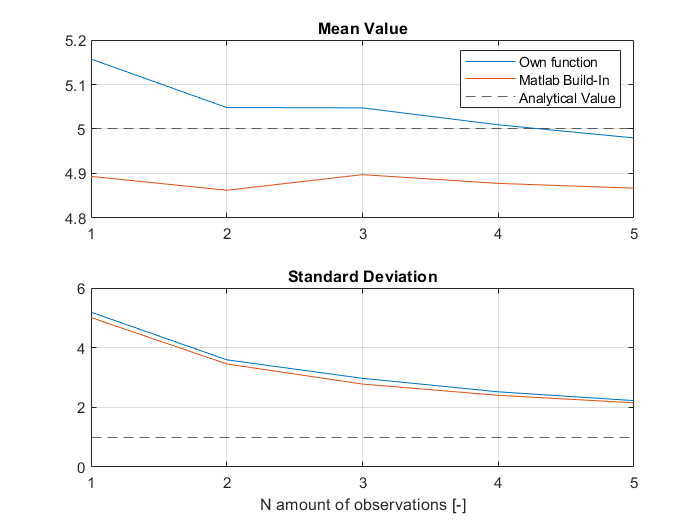

% ---------------------------------------------
% Create two subplots one for mean, and another for variance of the RVs
% generated by your own created function (3c), and by MATLAB build-in function
% (3d). You should have 'N' as your x-axis, and use 'hold on' to plot two
% curves in one subplot. 
% ---------------------------------------------
% First calculate the mean and std for the samples
for i = 1:N
    mean_own_function(i)=mean(Exp_dist(i).X);
    std_own_function(i)=std(Exp_dist(i).X);
    
    mean_matlab(i)=mean(Exp_dist_random(i).X);
    std_matlab(i)=std(Exp_dist_random(i).X);
end

figure(1)
subplot(2,1,1) %Produce the mean plot
plot([1:N],mean_own_function)
hold on
plot([1:N],mean_matlab)
yline((1/lambda),'--')
set(gca,'XTick',(0:1:M))
title('Mean Value')
legend('Own function','Matlab Build-In','Analytical Value')
grid on

subplot(2,1,2) %Produce the std plot
plot([1:N],std_own_function)
hold on
plot([1:N],std_matlab)
yline(1,'--')
xlabel('N amount of observations [-]')
set(gca,'XTick',(0:1:M))
title('Standard Deviation')
grid on

**ANSWER:**

Yes, it is visible that the more observation we take the estimate goes to the true mean value of the exponential distribution calculated in 3a and also the standard deviation decreases. 

## Assignment 4 - Central limit theorem

The central limit theorem states that the CDF of the sum of $N$ IID random variables converges to a Gaussian CDF for $N$ "sufficiently large". The following assignement give insights on how large should $N$ be. In this case, we will costruct a random variable $Z_N \left\lbrack n\right\rbrack$ as the **normalized** sum of $N$ RVs $x_i$ as follows:


$$Z_N =\frac{\frac{1}{N}\sum_{i=1}^N x_i -\mu_{X_N } }{\sigma_{X_N } }=\frac{X_N -\mu_{X_N } }{\sigma_{X_N } }\;\;\;\;\;\;\;\;\;\textrm{with}\;N=1,2,\ldotp \ldotp \ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(6\right)$$


where each $x_i$ is IID.

**QUESTION 4a**

Generate $X_{\textrm{uN}}$ and $X_{\textrm{eN}}$ as in previous assignements for $N=1$. (You can use MATLAN function 'random' to generate both RVs.) Construct the **normalized histogram**, adjusting the bin height to show the relative frequency and the bin location so that the bins are centered. Make a subplot of the adjusted histogram for each case, using 20 bins. What does the histogram represent?

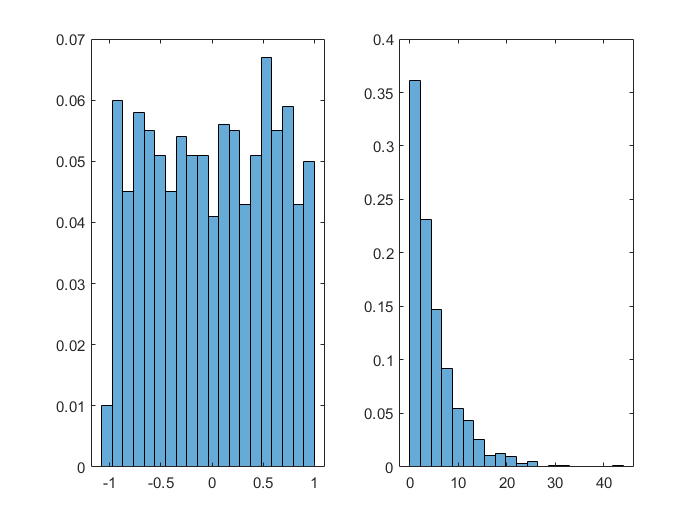

% ---------------------------------------------
% First, you need to generate XuN and XeN
% Then, you need to create a normalized histogram for XuN and XeN. 
% (The correct use of MATLAB function 'histogram' will help you)
% Finally, you make subplots to display your results. 
% ---------------------------------------------
% your code goes here (~15 lines of code)


nSamples = 1000;
nbins = 20;
a = -1;
b = 1;
lambda = 0.2;

P_uni=random('Uniform',a,b,[nSamples 1]);
P_exp=random('exp',(1/lambda),[nSamples 1]);

N = 1;

Xun = (1/N)*P_uni;
Xen = (1/N)*P_exp;

figure,
subplot(1,2,1)
histogram(Xun,nbins,'Normalization',"probability");  
    % Check 'doc histogram' if you don't know how to create normalized histogram
subplot(1,2,2)
histogram(Xen,nbins,'Normalization',"probability");

**ANSWER:**

Since in this case N=1, the histogram represents the pdf of the uniform and exponential distribution.

**QUESTION 4b**

Generate $Z_{\textrm{uN}}$ and $Z_{\textrm{eN}}$ for $N=1,\;5,\;\textrm{and}\;20$, as in Eq. (6), and make a **2-by-3 subplot** to show each case ($Z_{\textrm{u1}} ,Z_{\textrm{u5}} ,Z_{\textrm{u20}} ,Z_{\textrm{e1}} ,Z_{\textrm{e5}} ,Z_{\textrm{e20}}$). Plot on top of each adjusted histogram a normal distribution with zero mean and unite variance. How do the plot compare with increasing $N$? Which distribution converges faster to a normal distribution? Can you give a possible explanation?

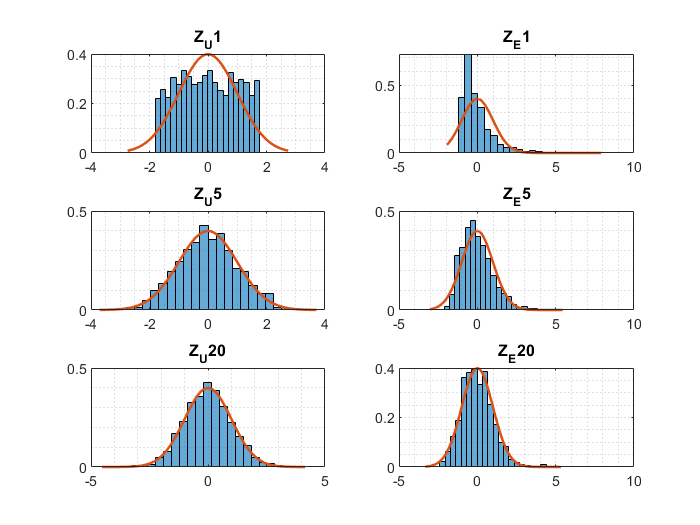

ax =   1×6 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes


ax =   1×6 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes


ax =   1×6 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes


ax =   1×6 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes


ax =   1×6 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes


ax =   1×6 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes


% ---------------------------------------------
% First calcualte ZuN and ZeN for N = 1, 5, and 20
% Then use MATLAB function 'pdf' to generate the normal distribution
% Use 'hold on' to plot the histogram and normal distribution curve in one
% plot. 
% ---------------------------------------------
% your code goes here (~15 lines of code)

N = [1, 5, 20];
count = 1;

for i = N 
    
    uni(count).sum = zeros(nSamples,1); %Initialise sum of i'th observation
    exp(count).sum = zeros(nSamples,1);
    
    for j=1:i 
        uni(count).sum = uni(count).sum + random('Uniform',a,b,[nSamples 1]);
        exp(count).sum = exp(count).sum + random('exp',(1/lambda),[nSamples 1]);
    end
    
    uni(count).X = (1/i)*uni(count).sum;   exp(count).X = (1/i)*exp(count).sum;
    
    uni(count).muX = mean(uni(count).X);   uni(count).stdX = std(uni(count).X);
    exp(count).muX = mean(exp(count).X);   exp(count).stdX = std(exp(count).X);
    
    uni(count).Z = (uni(count).X-uni(count).muX)/uni(count).stdX;
    exp(count).Z = (exp(count).X-exp(count).muX)/exp(count).stdX;
    
    count = count+1;
end

%Plot
count = 1;

figure()
for i=1:2:2*length(N)
    ax(i) = subplot(3,2,i)
    histogram(uni(count).Z,nbins,'Normalization',"pdf");
    hold on
    x = min(uni(count).Z)-1:abs(min(uni(count).Z)/100):max(uni(count).Z)+1;
    y = normpdf(x,0,1);
    plot(x,y,'LineWidth',1.5)
    grid minor
    title(['Z_U' num2str(N(count))])
    
    ax(i+1) = subplot(3,2,i+1)
    histogram(exp(count).Z,nbins,'Normalization',"pdf");
    hold on
    x = min(exp(count).Z)-1:abs(min(exp(count).Z)/100):max(exp(count).Z)+1;
    y = normpdf(x,0,1);
    plot(x,y,'LineWidth',1.5)
    grid minor
    title(['Z_E' num2str(N(count))])

    count=count+1;
end

**ANSWER:**

As N increases the plot resembles the Gaussian distribution more. The Uniform distribution converges faster to a Gaussian distribution then the exponential distribution. The uniform distribution converges faster, because it is already symmetrical. The exponential distribution still looks a bit skewed after N=5.

## **Assignment 5 - Maximum likelihood estimation**

The maximum-likelihood estimator (MLE) for scalar parameters is defined as the value of $\theta$ the maximizes $p\left(x;\theta \right)$ for x fixed, i. e., the likelihood function. The maximization is performed over all allowable range of $\theta$. The MLE is asymptotically optimal, i.e., for $N$ sufficiently large it is unbiased and reaches the CRLB.

The advantage of the MLE is that we can always find it for a given dataset numerically. When a grid search (trying all possible value of $\theta$ in a range) is not feasible, iterative maximization approaches can be used. One such approach is the Newton-Raphson method, which attempt to maximize the log-likelihood ln $p\left(x;\theta \right)$ by finding the zero of its derivative. To find the zero of $g\left(\theta \right)$ defined as


$$g\left(\theta \right)=\frac{\partial \ln \;p\left(x;\theta \right)}{\partial \theta }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\right)$$


the Newton-Raphson starts from an initial guess $\theta_0$ and makes a linear approximation of $g\left(\theta \right)$ around $\theta_0$. The guess for $\theta$ is then updated at each iteration k as


$$\theta_{k+1} =\theta_k -\frac{g\left(\theta_k \right)}{\frac{\partial g\left(\theta \right)}{\partial \theta }{\left|\right.}_{\theta =\theta_k } }\;\;\;\;\;\;\;\;\;\left(8\right)$$


The update is repeated until convergence, i.e., when $g\left(\theta_k \right)\sim 0$, or when a maximum number of iteration is reached. It is important to point out that the Netwon-Raphson method may not converge. This problem can particularly occur when the second derivative of the log-likelihood is small, causing the correction term to fluctuate widely at each iteration. Moreover, if the log-likelihood has multiple peaks, the algorithm may converge to a local maximum instead of the global optimum. This will strongly depend on the choice of the initial guess.

In the following assignment, we will investigate the importance of the initial guess for iterative optimization. We will implement Netwon-Raphson optimization to calculate the MLE from the random signal in **measured_signal.mat**, which can be modeled as


$$x\left\lbrack n\right\rbrack =\exp \left(\theta^2 \right)+w\left\lbrack n\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\left(9\right)$$


where $w\left\lbrack n\right\rbrack$ is AWGN, and the samples in $x\left\lbrack n\right\rbrack$ are IID.

**QUESTION 5a**

Load the signal in **measured_signal.mat** and plot the histogram. Which is roughly the most probable value of $x\left\lbrack n\right\rbrack$ ? Can you find an expression for calculating $\theta$ based on this observation?

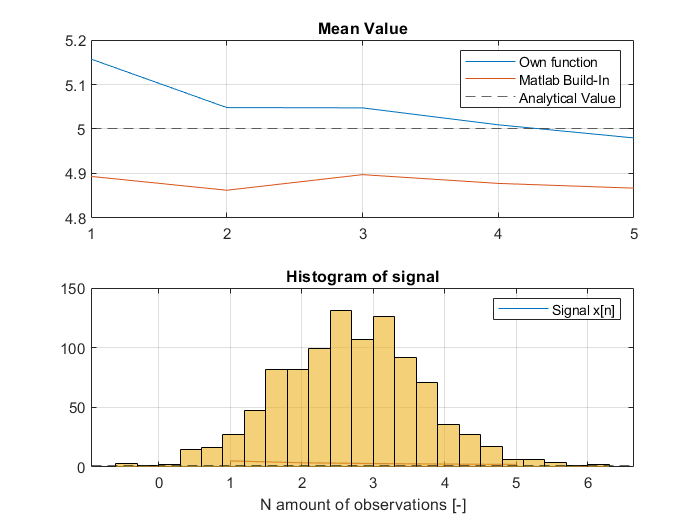

% ---------------------------------------------
% load measured_signal.mat, and plot the histogram.
% ---------------------------------------------

load("measured_signal.mat")
figure(1)
histogram(x)
title('Histogram of signal')
legend('Signal x[n]')

**ANSWER:**

The data seems to follow a gaussian distribution with mean around 2.8. 

The distribution is not 100% gaussian for which the noise is to blame. As we know the mean of the distribution is the most likely. This means that the most likely theta can be found by


$$E\left\lbrack x\right\rbrack \approx E\left\lbrack \exp \left(\theta^2 \right)\right\rbrack =2\ldotp 8\;\;\;\;$$



$$\theta =\sqrt{\ln \left(2\ldotp 8\right)}=1\ldotp 0147\;\;\;$$


**QUSTION 5b**

Give an expression for the $\ln \;p\left(x;\theta \right)$of the model in Eq. (9), and derive by hand the first and second derivative.

**ANSWER**: Please insert the analytical expression here.

The probability density function can be defined as:


$$p\left(x;\theta \right)=\frac{1}{{\left(2\pi \sigma^2 \right)}^{\frac{N}{2}} }e^{-\frac{\left(\sum_0^{N-1} {\left(x\left\lbrack n\right\rbrack -e^{\theta^2 } \right)}^2 \right)}{2\sigma^2 }}$$



$$\ln \left(p\left(x;\theta \right)\right)=-\ln \left({\left(2\pi \sigma^2 \right)}^{\frac{N}{2}} \right)-\frac{\left(\sum_0^{N-1} {\left(x\left\lbrack n\right\rbrack -e^{\theta^2 } \right)}^2 \right)}{2\sigma^2 }$$



$$\frac{d}{\mathrm{d}\theta }\ln \left(p\left(x;\theta \right)\right)=\frac{\left(\sum_0^{N-1} \left(x\left\lbrack n\right\rbrack -e^{\theta^2 } \right)2\theta e^{\theta^2 } \right)}{\sigma^2 }$$



$$\frac{d^2 }{\mathrm{d}\theta^2 }\ln \left(p\left(x;\theta \right)\right)=\frac{\left(\sum_0^{N-1} \left(x\left\lbrack n\right\rbrack -e^{\theta^2 } \right)\left(2e^{\theta^{2\;} } +4\theta^{2\;} e^{\theta^{2\;} } \right)-4\;\theta^{2\;} e^{2\theta^{2\;} } \;\right)\;}{\sigma^2 }$$


**QUESTION 5c**

Implement Netwton-Raphson iterative optimization to find $\overset{\wedge }{\;\theta_{\textrm{ML}} }$. Repeat three times using as initial guesses $\theta_0 =-1\ldotp 2$, $\theta_0 =0\ldotp 2$, and $\theta_0 =0\ldotp 8$. Is $\overset{\wedge }{\;\theta_{\textrm{ML}} }$ estimated in the three cases the same? Can you give a possible explanation?

clear exp
thetaML=[-1.2 0.2 0.8];
for p=1:length(thetaML)
    tolerance = 10^-4;


    dgdth = (sum((x - exp(thetaML(p)^2))* 2*thetaML(p)*exp(thetaML(p)^2)) )/1^2;
    while abs(dgdth)>tolerance
        % first order derivative
        dgdth = (sum((x - exp(thetaML(p)^2))* 2*thetaML(p)*exp(thetaML(p)^2)) )/1^2;
        % second order derivative
        d2gdth2= ((sum((x - exp(thetaML(p)^2))* (2*exp(thetaML(p)^2)+ ...
            4*thetaML(p)^2 * exp(thetaML(p)^2)) - 4* thetaML(p)^2 *exp(2*thetaML(p)^2) ))) ;
        % update theta
        
        thetaML(p) = thetaML(p) - dgdth/d2gdth2;
    end
    
   loglike(p)= -(length(x)/2)*log(2*pi*1^2) - (sum(x - exp(thetaML(p)^2))^2)/2;
    
end

**ANSWER:**

The three initial guesses result in three different values for theta. $\theta_0 =-1\ldotp 2$ results in a value of ${\theta^ˆ }_{\textrm{ml}} =-0\ldotp 9939$, $\theta_0 =0\ldotp 2$ results in a value of ${\theta^ˆ }_{\textrm{ml}} =0$ and $\theta_0 =0\ldotp 8$ results in a value of ${\theta^ˆ }_{\textrm{ml}} =0\ldotp 9939$  

The reason for the different results has to do with the pdf itself.  For a negative initial guess a negative theta is obtained, as the first derivative only has theta squared terms, which always return a positive value. Thus when ${\theta^ˆ }_{\textrm{ml}} =-0\ldotp 9939$ the derivative will also be zero if ${\theta^ˆ }_{\textrm{ml}} =0\ldotp 9939$ also is a minima. For $\theta_0 =0\ldotp 2$ an estimate of ${\theta^ˆ }_{\textrm{ml}} =0$  also is a minima as the first derivative sum is multiplied by ${\theta^ˆ }_{\textrm{ml}}$ . Obviously when this is zero also the derivative will be zero.  

**QUESTION 5d**

Given the constraint $\theta >0\ldotp 1$, which $\overset{\wedge }{\;\theta_{\textrm{ML}} }$ would you choose from the three obtained? Why?

**ANSWER:**

As there is only one ${\theta^ˆ }_{\textrm{ml}}$ that is larger than 0.1 it is clear that ${\theta^ˆ }_{\textrm{ml}} =0\ldotp 9939$ is the best guess. This also is close to the initial guess.

## **Assignment 6 - Least-squares estimation**

In the assignment, you will implement and evaluate a source localization technique based on a least-squares estimator (LSE). Source localization in wireless networks is used to estimate the position of mobile users, also referred to as mobile stations (MS). Typical applications of source localization techniques are to pinpoint the location of an emergency caller in a cellular network or to determine the position of a robot in a factory building. 

Source localization algorithms typically estimate the position of an MS using distance information between an MS and multiple base stations (BS). Any quantity that depends on the distance can be used to obtain distance information between an MS and a BS. The most commonly used quantities are the received signal strength or the propagation time of a signal. In the latter approach, time-synchronized MS and BSs are used. The MS transmits a signal at a predefined time, for example, at $t=0$. The signal is received at the $i_{\textrm{th}}$ BS after 


$$
    \tau_i = d_i/c.\quad(10)
$$


Here, $d_i$ is the distance between the MS and the  $i_{\textrm{th}}$ BS given as 


$$  d_i =\sqrt{(x-x_i)^2 + (y-y_i)^2}, \quad (11)$$


where $\left(x_i ,y_i \right)$ are the coordinates of the $i_{\textrm{th}}$ BS, $\left(x,y\right)$ are the unknown coordinates of the MS, and $c$ is the speed of light. In general, distance information to three different BS is required to determine the position of the MS unambiguously, see figure below.

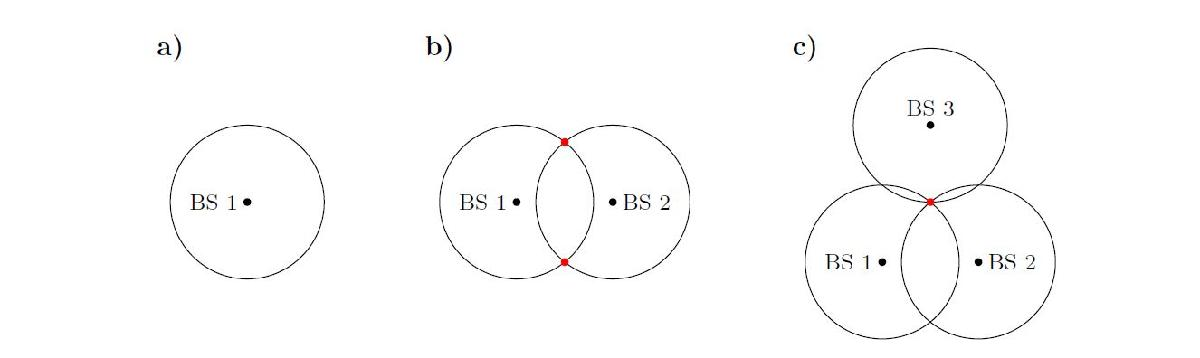

*Figure 1: *Localization principle: a) Distance information to a single BS restrict the MS's location to a circle with the BS at its center. b) Adding distance information of a second BS reduces the possible position of the MS to the two intersection points, and c) adding the distance information to a third BS resolves the location ambiguity.

In most cases, however, the distance information is corrupted by noise. For example, the measurement of the propagation time relies on timing information derived from local oscillators. These local oscillators, however, differ slightly from each other. We can model this timing inaccuracy as a noise added to the true distance, i.e., 


$$    r_i = d_i + n_i. \quad (12)$$


Due to noise, however, it is not possible anymore to determine the exact location of the BS; instead, estimation techniques must be applied.

We can use the LSE to estimate the position of an MS in a wireless network. The distance information and the Cartesian coordinates are related through the nonlinear relation in equation (11). However, it is possible to establish a linear relationship between the coordinates and the distance by introducing an auxiliary variable given as $R^2 = x^2+y^2$, which also needs to be estimated. 

**QUESTION 6a**

Transform the nonlinear relation (11) into a linear relation and express the estimation problem using a linear signal model of the form


$$\mathbf{b} = \mathbf{A}\mathbf{{\theta}}, \quad(13)$$


where the parameter vector is $\mathbf{\theta} = [x_,\quad y, \quad R^2]^T$. *HINT: consider the squared distance.*

**ANSWER**: (write here your workout)

Working out (11) we get:


$$d_i^2 =(x-x_i)^2 + (y-y_i)^2$$



$$d_i^2 =x^2-2x_ix+x_i^2 + y^2-2y_iy+y_i^2$$



$$d_i^2 =R^2-2x_ix-2y_iy+x_i^2 + y_i^2$$



$$d_i^2-R_i^2 =R^2-2x_ix-2y_iy$$



$$\mathbf{b}=[-2x_i, -2y_i,1][x, y, R^2]^T=d_i^2-R_i^2$$


**QUESTION 6b**

To evaluate the performance, we can compare the variance of the estimator to the CRLB. To obtain the CRLB, you need first to calculate the Fisher information matrix $$\mathbf{I}(\mathbf{\theta})$$ for the parameter vector $\mathbf{\theta} = [x,\quad y]^T$. The Fisher information matrix is given as


$$$\mathbf{I}(\mathbf{\theta})$$$

$$=\left\lbrack \begin{array}{cc}
-\mathrm{E}\left\lbrack \frac{\partial^2 }{\partial x^2 }\ln \;p\left(\mathbf{d};x,y\right)\right\rbrack  & -\mathrm{E}\left\lbrack \frac{\partial^2 }{\partial {x\partial y} }\ln \;p\left(\mathbf{d};x,y\right)\right\rbrack \\
-\mathrm{E}\left\lbrack \frac{\partial^2 }{\partial x\partial y}\ln \;p\left(\mathbf{d};x,y\right)\right\rbrack  & -\mathrm{E}\left\lbrack \frac{\partial^2 }{\partial y^2 }\ln \;p\left(\mathbf{d};x,y\right)\right\rbrack 
\end{array}\right\rbrack \;\;\;\;\;\left(14\right)$$


Assume that the additive noise is IID and normal distributed with zero mean and variance $\sigma^2$. Thus, the PDF of the distance measurement is 


$$  p(\mathbf{r};x,y) = \frac{1}{(2\pi\sigma^2)^{\frac{N}{2}}} \exp\left(-\frac{1}{2\sigma^2}\sum_{i=0}^{N-1}\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)^2\right). \quad (15)$$


Please derive the Fisher information matrix here. 

**ANSWER**: (write here your workout)

from (15) we can take:$ln\left(p(\mathbf{d};x,y)\right) = ln\left(\frac{1}{(2\pi\sigma^2)^{\frac{N}{2}}} \right)-\frac{1}{2\sigma^2}\sum_{i=0}^{N-1}\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)^2\$

then computing the first derivatives with respect to x we get:


$$\frac{\partial ln\left(p(\mathbf{d};x,y)\right) }{\partial x} = -\frac{1}{2\sigma^2}\sum_{i=0}^{N-1}\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{-2(x-x_i)}{\sqrt{(x-x_i)^2+(y-y_i)^2}}\right)$$


$\frac{\partial ln\left(p(\mathbf{d};x,y)\right) }{\partial x} = \frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{(x-x_i)}{\sqrt{(x-x_i)^2+(y-y_i)^2}}\right)$,

simmilarly for y we get


$$\frac{\partial ln\left(p(\mathbf{d};x,y)\right) }{\partial y} = -\frac{1}{2\sigma^2}\sum_{i=0}^{N-1}\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{-2(y-y_i)}{\sqrt{(x-x_i)^2+(y-y_i)^2}}\right)$$



$$\frac{\partial ln\left(p(\mathbf{d};x,y)\right) }{\partial y} = \frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{(y-y_i)}{\sqrt{(x-x_i)^2+(y-y_i)^2}}\right)$$


Through use of the product rule with the next steps we get to the first entry of the Fisher information matrix by:


$$\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial x^2} = \frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left\{\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{1}{\sqrt{(x-x_i)^2+(y-y_i)^2}}-\frac{(x-x_i)^2}{\left((x-x_i)^2+(y-y_i)^2\right)^{\frac{3}{2}}}\right)-\frac{(x-x_i)^2}{(x-x_i)^2+(y-y_i)^2}\right\}$$



$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial x^2} \right]= -E\left[\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left\{\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{1}{\sqrt{(x-x_i)^2+(y-y_i)^2}}-\frac{(x-x_i)^2}{\left((x-x_i)^2+(y-y_i)^2\right)^{\frac{3}{2}}}\right)-\frac{(x-x_i)^2}{(x-x_i)^2+(y-y_i)^2}\right\}\right]$$


Since only $d_i
$ are the observations and the rest can be seen as constants we can write it as:


$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial x^2} \right]= -\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left\{\left(E\left[d_i \right]- \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{1}{\sqrt{(x-x_i)^2+(y-y_i)^2}}-\frac{(x-x_i)^2}{\left((x-x_i)^2+(y-y_i)^2\right)^{\frac{3}{2}}}\right)-\frac{(x-x_i)^2}{(x-x_i)^2+(y-y_i)^2}\right\}$$


and since $E\left[d_i \right]=\sqrt{(x-x_i)^2+(y-y_i)^2}$. A whole part can be left out since it wil be multiplied by zero. We are left with:


$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial x^2} \right]= -\frac{1}{\sigma^2}\sum_{i=0}^{N-1}-\frac{(x-x_i)^2}{(x-x_i)^2+(y-y_i)^2}$$



$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial x^2} \right]= \frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(x-x_i)^2}{(x-x_i)^2+(y-y_i)^2}$$


The right bottom element of the Fisher information matrix can be deduced similarly through:


$$\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial y^2} = \frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left\{\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{1}{\sqrt{(x-x_i)^2+(y-y_i)^2}}-\frac{(y-y_i)^2}{\left((x-x_i)^2+(y-y_i)^2\right)^{\frac{3}{2}}}\right)-\frac{(y-y_i)^2}{(x-x_i)^2+(y-y_i)^2}\right\}$$



$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial y^2} \right]= -E\left[\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left\{\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{1}{\sqrt{(x-x_i)^2+(y-y_i)^2}}-\frac{(y-y_i)^2}{\left((x-x_i)^2+(y-y_i)^2\right)^{\frac{3}{2}}}\right)-\frac{(y-y_i)^2}{(x-x_i)^2+(y-y_i)^2}\right\}\right]$$


Since only $d_i
$ are the observations and the rest can be seen as constants we can write it as:


$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial y^2} \right]= -\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left\{\left(E\left[d_i \right]- \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{1}{\sqrt{(x-x_i)^2+(y-y_i)^2}}-\frac{(y-y_i)^2}{\left((x-x_i)^2+(y-y_i)^2\right)^{\frac{3}{2}}}\right)-\frac{(y-y_i)^2}{(x-x_i)^2+(y-y_i)^2}\right\}$$


and since $E\left[d_i \right]=\sqrt{(x-x_i)^2+(y-y_i)^2}$. A whole part can be left out since it wil be multiplied by zero. We are left with:


$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial y^2} \right]= \frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(y-y_i)^2}{(x-x_i)^2+(y-y_i)^2}$$


For the case where partial derivation for x and then y is done we get the same as for doing first y and then x so:


$$\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial x \partial y} = \frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left\{\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(-\frac{(x-x_i)(y-y_i)}{\left((x-x_i)^2+(y-y_i)^2\right)^{\frac{3}{2}}}\right)-\frac{(x-x_i)(y-y_i)}{(x-x_i)^2+(y-y_i)^2}\right\}$$



$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial x \partial y} \right]= -E\left[\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left\{\left(d_i - \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(-\frac{(x-x_i)(y-y_i)}{\left((x-x_i)^2+(y-y_i)^2\right)^{\frac{3}{2}}}\right)-\frac{(x-x_i)(y-y_i)}{(x-x_i)^2+(y-y_i)^2}\right\}\right]$$


Since only $d_i
$ are the observations and the rest can be seen as constants we can write it as:


$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial x \partial y} \right]= -\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\left\{\left(E\left[d_i \right]- \sqrt{(x-x_i)^2+(y-y_i)^2}\right)\left(-\frac{(x-x_i)(y-y_i)}{\left((x-x_i)^2+(y-y_i)^2\right)^{\frac{3}{2}}}\right)-\frac{(x-x_i)(y-y_i)}{(x-x_i)^2+(y-y_i)^2}\right\}$$


and since $E\left[d_i \right]=\sqrt{(x-x_i)^2+(y-y_i)^2}$. A whole part can be left out since it wil be multiplied by zero. We are left with:


$$-E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial x\partial y} \right]= -E\left[\frac{\partial^2 ln\left(p(\mathbf{d};x,y)\right) }{\partial y\partial x} \right]= \frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(x-x_i)(y-y_i)}{(x-x_i)^2+(y-y_i)^2}$$


This combined with the previous results comes down to a fisher information matrix of:


$$$\mathbf{I}(\mathbf{\theta})$$$

$$=\left\lbrack \begin{array}{cc}
-\mathrm{E}\left\lbrack \frac{\partial^2 }{\partial x^2 }\ln \;p\left(\mathbf{d};x,y\right)\right\rbrack  & -\mathrm{E}\left\lbrack \frac{\partial^2 }{\partial x\partial y}\ln \;p\left(\mathbf{d};x,y\right)\right\rbrack \\
-\mathrm{E}\left\lbrack \frac{\partial^2 }{\partial x\partial y}\ln \;p\left(\mathbf{d};x,y\right)\right\rbrack  & -\mathrm{E}\left\lbrack \frac{\partial^2 }{\partial y^2 }\ln \;p\left(\mathbf{d};x,y\right)\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{{\left(x-x_i \right)}^2 }{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 } & \frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{\left(x-x_i \right)\left(y-y_i \right)}{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 }\\
\frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{\left(x-x_i \right)\left(y-y_i \right)}{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 } & \frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{{\left(y-y_i \right)}^2 }{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 }
\end{array}\right\rbrack$$


**QUESTION 6c**

Determine the Cramer-Rao Lower Bound based on the Fisher infomation matrix you got from 6b. 

**ANSWER**: (write here your workout)

We can get the Cramer-Rao Lower Bound by talking the inverse of the Fisher information matrix which is $$\mathbf{I}(\mathbf{\theta})^{-1}$ = $\frac{1}{ad-bc}$$$\left\lbrack \begin{array}{cc}
d & -b\\
-c & a
\end{array}\right\rbrack$ if the Fisher matrix is of the form 

$$\mathbf{I}(\mathbf{\theta})$ = $$\left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack$. This results in:


$$$\mathbf{I}(\mathbf{\theta})^{-1}$ =$$

$$\frac{1}{\left(\frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{{\left(x-x_i \right)}^2 }{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 }\right)\left(\frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{{\left(y-y_i \right)}^2 }{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 }\right)-{\left(\frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{\left(x-x_i \right)\left(y-y_i \right)}{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 }\right)}^2 }\left\lbrack \begin{array}{cc}
\frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{{\left(y-y_i \right)}^2 }{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 } & -\frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{\left(x-x_i \right)\left(y-y_i \right)}{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 }\\
-\frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{\left(x-x_i \right)\left(y-y_i \right)}{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 } & \frac{1}{\sigma^2 }\sum_{i=0}^{N-1} \frac{{\left(x-x_i \right)}^2 }{{\left(x-x_i \right)}^2 +{\left(y-y_i \right)}^2 }
\end{array}\right\rbrack$$


From this matrix we can take element (1,1) as the Cramer-Rao Lower bound for x so:


$$CRLB_x= \frac{\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(y-y_i)^2}{(x-x_i)^2+(y-y_i)^2}}{\left(\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(y-y_i)^2}{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(x-x_i)^2}{(x-x_i)^2+(y-y_i)^2}\right)-\left(\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(x-x_i)(y-y_i)}{(x-x_i)^2+(y-y_i)^2}\right)^2}$$


For the bound at y we take (2,2) of the matrix above so:


$$CRLB_y= \frac{\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(x-x_i)^2}{(x-x_i)^2+(y-y_i)^2}}{\left(\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(y-y_i)^2}{(x-x_i)^2+(y-y_i)^2}\right)\left(\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(x-x_i)^2}{(x-x_i)^2+(y-y_i)^2}\right)-\left(\frac{1}{\sigma^2}\sum_{i=0}^{N-1}\frac{(x-x_i)(y-y_i)}{(x-x_i)^2+(y-y_i)^2}\right)^2}$$


**QUESTION 6d**

Now, we would like to implement the above-mentioned problem in MATLAB. Please first run the following script. You will see four BS (red cross) and a MS (blue cross). 

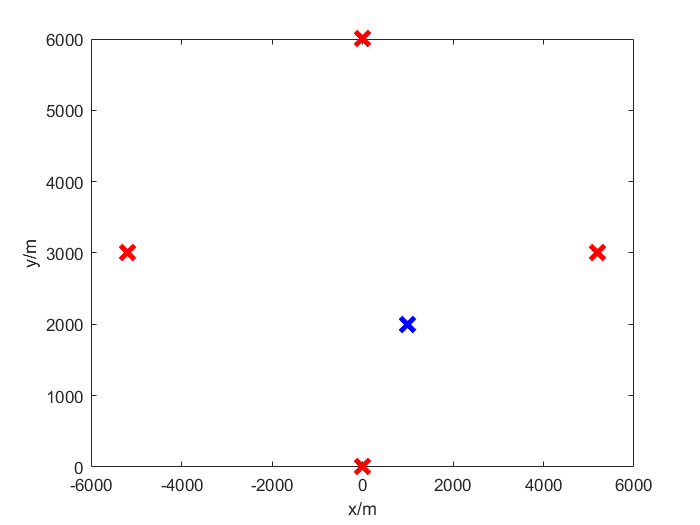

% Base station (bs) and mobile station (ms) position
bs_pos = [0                 0;
          3000*sqrt(3)      3000;
          0                 6000;
          -3000*sqrt(3)     3000];     % Position of 4 base stations
                 
N_bs = size(bs_pos,1);          % number of base stations
 
ms_pos = [1000,2000];           % Position of the mobile station
       
figure
plot(bs_pos(:,1),bs_pos(:,2),'rx','MarkerSize', 12, 'LineWidth', 3)
hold on
plot(ms_pos(1),ms_pos(2),'bx','MarkerSize', 12, 'LineWidth', 3)
xlabel('x/m')
ylabel('y/m')

Your task is to implement a LSE to estimate the location of the MS with a Monte-Carlo simulation, and to check whether your estimation matches the real MS location. 

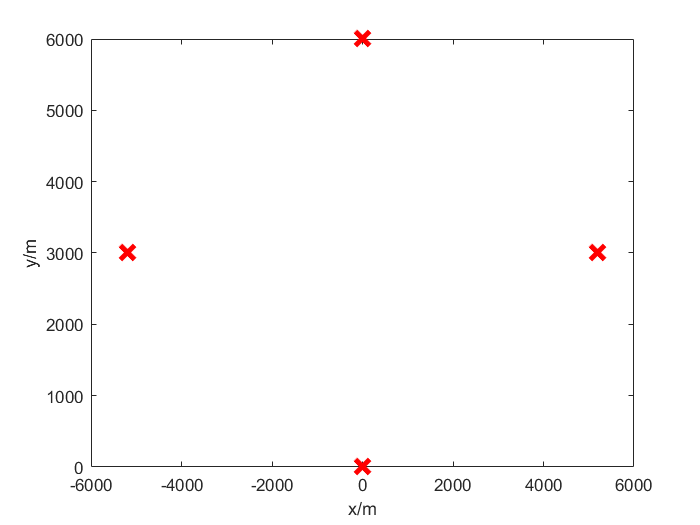

sigma2_dB = 25; %% noise is added to the distance measuremnt which is in m. 
                %Thus, the variance is m^2.  
                % For higher dynamic range, we can use dB, 
                %which in this case becomes dBm^2 since the reference quantity is m^2. 
sigma2_lin = 10^(sigma2_dB/10); 
 
N_mc = 1e3; % # 1000 times of Monte Carlo simulations 
 
    d = sqrt((ms_pos(1) - bs_pos(:,1)).^2 + (ms_pos(2) - bs_pos(:,2)).^2);  
        % The real distance between base stations and MS
    A = [-2*bs_pos(:,1), -2*bs_pos(:,2),ones(N_bs,1)];  
        % The matrix to linearize the relation 
    R2 = sqrt((bs_pos(:,1)).^2 + (bs_pos(:,2)).^2);  
        % The squared distance of the basestations
 
 
 
% compute estimates 
for i_mc = 1:N_mc 
    % define your LS estimator (The variable name defined here corresponds to QUESTION 6a-c) 
    d_tmp = d+sqrt(sigma2_lin)*randn(N_bs,1);   
        % noisy distance measurment 
    b = d_tmp.^2 - R2.^2 ;                        
        % The definition of b is the distance between the 
        % noisy distance measurement and the base stations                                 
    theta(:,i_mc) = A\b ;     
        % theta is the matrix of x, y and R^2 as defined in 6a 
end 
 
figure 
plot(bs_pos(:,1),bs_pos(:,2),'rx','MarkerSize', 12, 'LineWidth', 3) 
hold on 
xlabel('x/m') 
ylabel('y/m') 

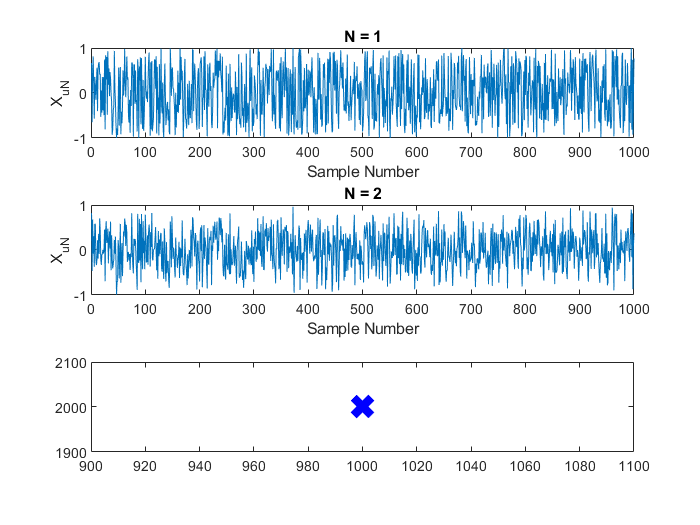

figure(2) 
plot(theta(1,:),theta(2,:),'xk'); 
plot(ms_pos(:,1),ms_pos(:,2),'bx','MarkerSize', 15, 'LineWidth', 5) 
xlim([900,1100]) 
ylim([1900,2100]) 

**QUESTION 6e**

Evaluate the performance for $\sigma^2$ from 20 to 70 dB in 5 dB steps and for 1000 realizations. Plot the mean squared range error (MSRE) given as $E\left({\left(\hat{x} -x\right)}^2 +\left(\hat{y} -y\right)\right)$ in $\textrm{dB}m^2$ vs. the noise variance in $\textrm{dB}m^2$, where $\hat{x}$ and $\hat{y}$ are the estimated poisitions, and $x$ and $y$ are the real poisitions of MS. 

sigma2_dB = 20:5:70;
sigma2_lin = 10.^(sigma2_dB/10);
N_mc = 1e3;  % # 1000 times of Monte Carlo simulations

sre = zeros(N_mc,1);                    % squared range error    
msre = zeros(length(sigma2_dB),1);      % mean squared range error

for i_sigma2 = 1:length(sigma2_dB)
    for i_mc = 1:N_mc
         d_tmp = d+sqrt(sigma2_lin(i_sigma2))*randn(N_bs,1);            
             % noisy distance measurment
         b = d_tmp.^2 - R2.^2 ;                                    
             % The definition of b is the distance between the 
             %noisy distance measurement and the base stations
         theta(:,i_mc)= A\b;                                      
             % theta is the matrix of x, y and R^2 as defined in 6a
         sre(i_mc) = (theta(1,i_mc)-ms_pos(1))^2+(theta(2,i_mc)-ms_pos(2))^2;      
             % squared range error per MC simulation, 
             % where theta(1,i_mc) is the x value for iteration i_mc
    end
    msre(i_sigma2) = mean(sre(:));                  
        % mean of all squared range error
end

msre_dB = 10*log10(msre)                % MSRE in dB

msre_dB =    20.5573
   25.6739
   30.4437
   35.5017
   40.3952
   45.5548
   50.5359
   55.7655
   60.5844
   66.1811


figure
plot(sigma2_dB,msre_dB);
hold on
xlabel('\sigma^2/dBm^2')
ylabel('msre/dBm^2')



**QUESTION 6f**

Calculate the CRLB and comapre it with the MSRE obtained by LSE. 

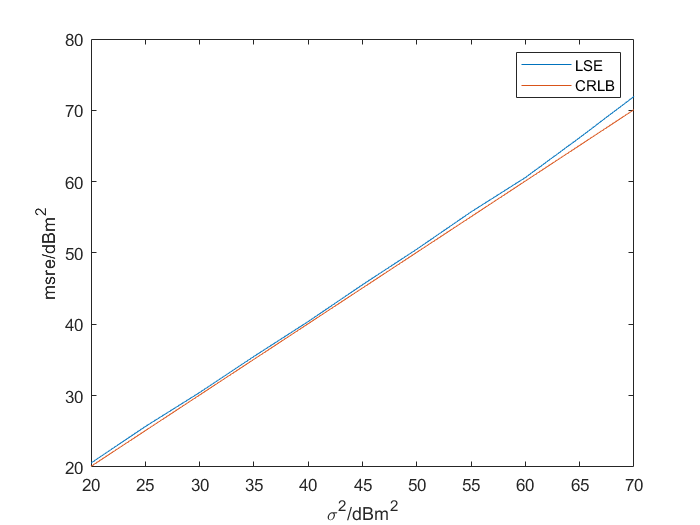

x_dist = ms_pos(1)-bs_pos(:,1);
y_dist = ms_pos(2)-bs_pos(:,2);

% entries of Fisher information matrix [a, b; c, d] (b = c)
a = 1./(sigma2_lin).*sum((x_dist).^2./(x_dist.^2+y_dist.^2)); 
    % Element (1,1) of the fisher information matrix defined in 6b
c = 1./(sigma2_lin).*sum((x_dist.*y_dist)./(x_dist.^2+y_dist.^2)); 
    % Element (1,2) and (2,1) of the fisher information matrix defined in 6b
b = 1./(sigma2_lin).*sum((y_dist).^2./(x_dist.^2+y_dist.^2)); 
    % Element (2,2) of the fisher information matrix defined in 6b


det_I = 1./(a.*b-c.^2); % determinant of Fisher information matrix as in 6c

crlb_x = det_I.*b; %CRLB as defined in 6c
crlb_y = det_I.*a; %CRLB as defined in 6c

crlb_msre = crlb_x+crlb_y;
plot(sigma2_dB,10*log10(crlb_msre));
legend({'LSE','CRLB'})